% Determine the probability of a data frame of 100 Bytes to be received without errors when
% 𝑝 = 10−2. Answer: 0.0322;


p = 10^-2; % Probability of error
frameSize = 100; % Size of the data frame in Bytes
numBits = frameSize * 8; % Convert Bytes to bits


% prob_0 = nchoosek(n,0) * p^0 * (1-p)(n-0)


prob_0 = 1 * p^0 * (1-p)^(numBits-0);
perc_0 = prob_0 * 100

perc_0 = 0.0322




% Determine the probability of a data frame of 1000 Bytes to be received with exactly one
% error when 𝑝 = 10−3. Answer: 0.2676


p = 10^-3; % Probability of error
frameSize = 1000; % Size of the data frame in Bytes
numBits = frameSize * 8; % Convert Bytes to bits


% prob_0 = nchoosek(n,0) * p^0 * (1-p)(n-0)


prob_1 = nchoosek(numBits,1) * p^1 * (1-p)^(numBits-1);
perc_1 = prob_1 * 100

perc_1 = 0.2676





% Determine the probability of a data frame of 200 Bytes to be received with one or more
% errors when 𝑝 = 10−4. Answer: 14.7863

p = 10^-4; % Probability of error
frameSize = 200; % Size of the data frame in Bytes
numBits = frameSize * 8; % Convert Bytes to bits

prob_0 = 1 * p^0 * (1-p)^(numBits-0);

prob_1_p = 1 - prob_0;

perc_1_p = prob_1_p * 100

perc_1_p = 14.7863

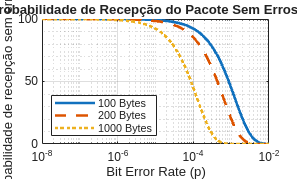



% Draw a plot using a logarithmic scale for the X-axis (use the MATLAB function
% semilogx) with the probability of a data frame (of
% size 100 Bytes, 200 Bytes or 1000 Bytes) being received without errors as a function of
% the ber (from 𝑝 = 10−8 up to 𝑝 = 10−2). What do you conclude from these results?

% --- 2.d) Plotagem da Probabilidade de Recepção Sem Erros ---

% 1. Definir o vetor de taxas de erro de bit (ber = p)
% O enunciado pede de p = 10^-8 até p = 10^-2
p = logspace(-8, -2, 100); % Cria 100 pontos logaritmicamente espaçados

% 2. Definir os tamanhos dos data frames (em Bytes)
frameSizes = [100, 200, 1000]; % Tamanhos em Bytes

% 3. Converter os tamanhos para o número total de bits (N)
N_100Bytes = frameSizes(1) * 8; % N = 800 bits
N_200Bytes = frameSizes(2) * 8; % N = 1600 bits
N_1000Bytes = frameSizes(3) * 8; % N = 8000 bits

% 4. Calcular a Probabilidade de Recepção Sem Erros (P(0 erros))
% P(0 erros) = (1 - p)^N

% Para frame de 100 Bytes
P_noError_100 = (1 - p) .^ N_100Bytes; 

% Para frame de 200 Bytes
P_noError_200 = (1 - p) .^ N_200Bytes;

% Para frame de 1000 Bytes
P_noError_1000 = (1 - p) .^ N_1000Bytes;

% 5. Converter as probabilidades para percentagem
Perc_noError_100 = P_noError_100 * 100;
Perc_noError_200 = P_noError_200 * 100;
Perc_noError_1000 = P_noError_1000 * 100;

% 6. Plotar os resultados usando semilogx (eixo X logarítmico)
figure; % Cria uma nova janela de figura
semilogx(p, Perc_noError_100, '-', 'LineWidth', 2);
hold on; % Permite adicionar mais gráficos na mesma figura
semilogx(p, Perc_noError_200, '--', 'LineWidth', 2);
semilogx(p, Perc_noError_1000, ':', 'LineWidth', 2);
hold off;

% 7. Adicionar rótulos, título e grade
title('Probabilidade de Recepção do Pacote Sem Erros (%)');
xlabel('Bit Error Rate (p)');
ylabel('Probabilidade de recepção sem erros (%)');
grid on;
grid minor;
ylim([0 100]); % Garante que o eixo Y vá de 0 a 100%
xlim([10^-8 10^-2]); % Garante que o eixo X vá de 10^-8 a 10^-2

% 8. Adicionar legenda
legend('100 Bytes', '200 Bytes', '1000 Bytes', 'Location', 'southwest');